**Sample code**

Setting: helping the South African government understand the transport distances involved with placing a major grain storage facility at different nodes in the nation’s rail network. Because grain must be carried by train, the analysis focused on minimum distances along the railroad network. The goal is to develop an interactive tool that allows the policy makers to quickly analyze any potential site by simply specifying its location. The tool’s specification is that a user must be able to tell the program a location and the program should output a map depicting transport distances to all other nodes in the network.

clear
[s,a] = shaperead('ZAF_rrd/ZAF_rails.shp','UseGeoCoords', true);
[s_country,a_country] = shaperead('ZAF_adm/ZAF_adm0.shp','UseGeoCoords', true);

**Cleaning data**

**[code provided by professor]**

s = remove_extra_nans_in_polyline(s);

start_lat = nan(497,1);
start_lon = nan(497,1);
end_lat = nan(497,1);
end_lon = nan(497,1);
for i = 1:497
    start_lat(i) = s(i).Lat(1);
    start_lon(i) = s(i).Lon(1);
    end_lat(i) = s(i).Lat(end-1);
    end_lon(i) = s(i).Lon(end-1);
end

list_with_duplicates = [start_lat, start_lon; end_lat, end_lon];
stations = unique(list_with_duplicates, 'rows');
    %finding unique stations

**Plotting the unique stations in the network**

**[personal code]**

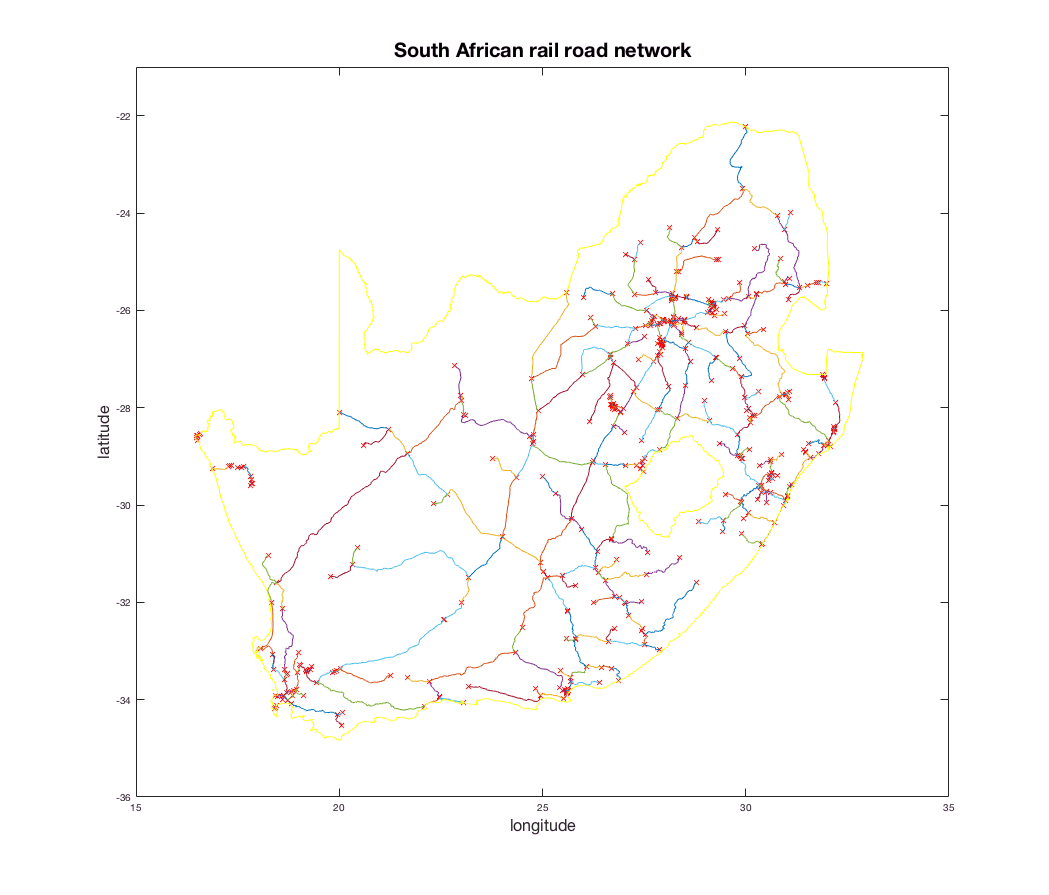

clf
fig = figure('Position', [0, 0, 1049, 895]);
plot(stations(:,2), stations(:,1), 'xr')
hold on
for i = 1:497
    plot(s(i).Lon, s(i).Lat)
end
plot(s_country.Lon, s_country.Lat, 'y')
axis([15 35 -36 -21])
title('South African rail road network', 'FontSize', 20)
xlabel('longitude', 'FontSize', 16)
ylabel('latitude', 'FontSize', 16)

**Constructing the adjaciency matrix (describing which stations are directly linked to other stations) and finding the distances**

**[code provided by professor]**

L = zeros(length(stations));
D = Inf(length(stations));
dist = Inf;
for i = 1:length(s)
    for j = 1:length(stations)
        if [s(i).Lat(1), s(i).Lon(1)] == stations(j,:)
            start_j = j;
        end
        if [s(i).Lat(end-1), s(i).Lon(end-1)] == stations(j,:)
            end_j = j;
        end
    end
    dist = sqrt((stations(end_j, 1)-stations(start_j, 1))^2 + ...
            (stations(end_j, 2)-stations(start_j, 2))^2);
    L(start_j, end_j) = 1;
    L(end_j, start_j) = 1;
    D(start_j, end_j) = dist;
    D(end_j, start_j) = dist;
end 

**Implementing Dijkstra's algorithm to find shortest path from one station (source) to all its connected stations**

**[personal code]**

**In this example, input = 461**

k = input(['Station for facility?  Enter 1 to ' num2str(length(stations)) ':  ']);
    %source node

D_dij = Inf(467,1);
P = NaN(467,1);
I = zeros(467,1);

parent_node = k;
D_dij(k) = 0;

%Dijkstra's algorithm
while sum(I) < 467
    
    I(parent_node) = 1;
    x = ([1:467]);                             
        %iterator for all possible connections of the adjaciency matrix
    [~,column] = find(L(parent_node,x)==1);    
        %find the connected nodes to the parent node in the L matrix
    column = column(I(column)==0);             
        %exclude connections that have been included in the network already
    
    if isempty(column)                         
        %if there are no more connections left in the path
        [row,~] = find(D_dij < Inf);           
            %go back to the previous parent node 
        new_parent = row(I(row)==0);
        if isempty(new_parent)                 
                %if all the connections have been explored, get out of the loop
            break
        end
        min(D_dij(new_parent));                
            %find the next path to walk over
        [parent_node,~] = find(D_dij==min(D_dij(new_parent)));    
            %find the row number in the D_dij matrix
        continue
    end
    
    distance = D(parent_node,column);          
        %find the distances between the node and all the possible connections
    
    for node = column                          
        %for every node that is a possible connection (for node in column)
        if D(parent_node,node) + D_dij(parent_node) < D_dij(node)     
                %if the new distance were smaller than the current one
            D_dij(node) = D(parent_node,node) + D_dij(parent_node);   
                %substitute with new distance
            P(node) = parent_node;                                    
                %set the parent node for the current node in the P matrix
        end      
    end
    
    min_distance = min(distance);               
        %find the minimum distance among the possible connections
    [match,~] = find(D==min_distance);          
        %find the row and column in the adjaciency matrix that give the min distance value
    
    if match(1) == parent_node                  
        %select the correct item in the match
        %(i.e. the one that is not currently the parent node)
        P(match(2)) = parent_node;
        parent_node = match(2);
    else
        P(match(1)) = parent_node;
        parent_node = match(1);
    end     
    
end

**Plotting the source (red circle) and all the connected stations, which are colored based on their distance from the source**

**[personal code]**

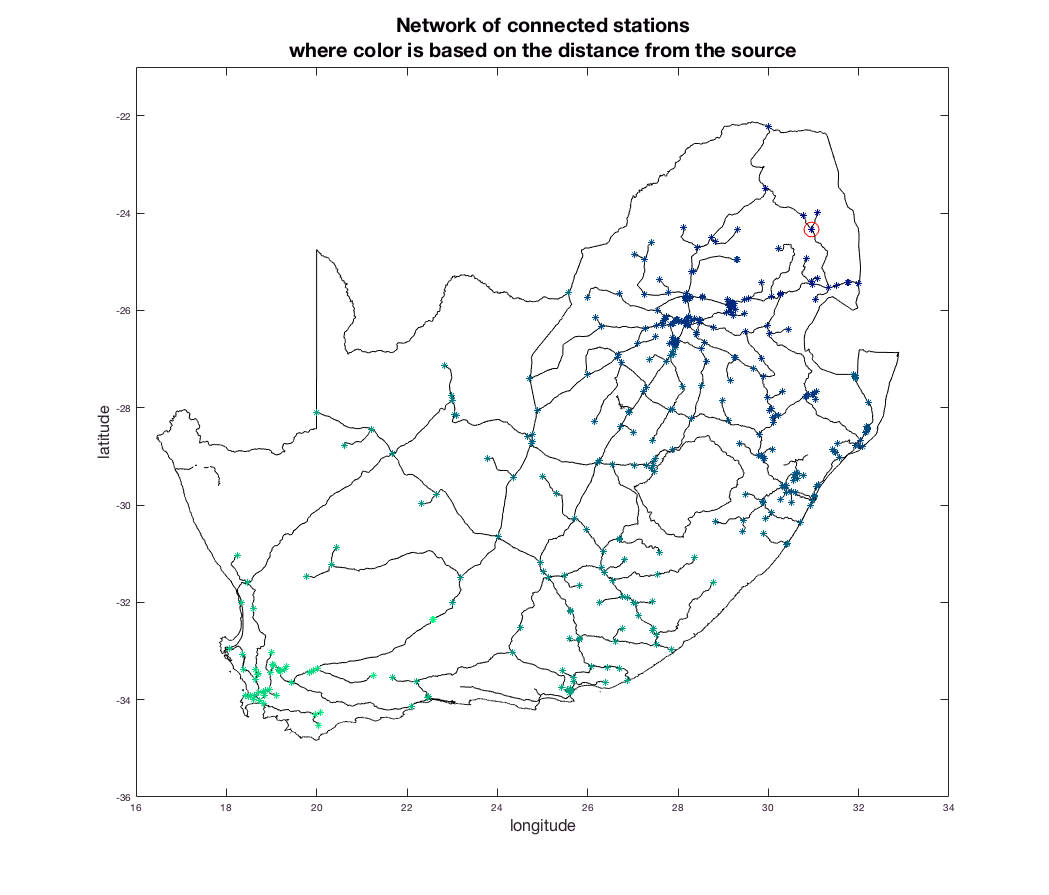

max_dist = max((D_dij(~isinf(D_dij))));            
colors = zeros(467,1);
%allows to plot stations colored based on their distances from the grain facility

clf
for i = 1:497
    plot(s(i).Lon, s(i).Lat, 'k')
    hold on
end
plot(s_country.Lon, s_country.Lat, 'k')
for i = 1:467
    if ~isinf(D_dij(i))
        colors(i) = D_dij(i)*(1/max_dist);
        plot(stations(i, 2), stations(i, 1), '*', 'Color', [0 colors(i) 0.5])
        hold on
    end
end
plot(stations(k, 2), stations(k, 1), 'ro', 'MarkerSize', 15)
axis ([16 34 -36 -21])
title({'Network of connected stations';
    'where color is based on the distance from the source'}, 'FontSize', 20)
xlabel('longitude', 'FontSize', 16)
ylabel('latitude', 'FontSize', 16)

**Plotting shortest distance between two stations overlaid on the complete network**

**[personal code]**

**In this example, source/input = station 345, final = station 33**

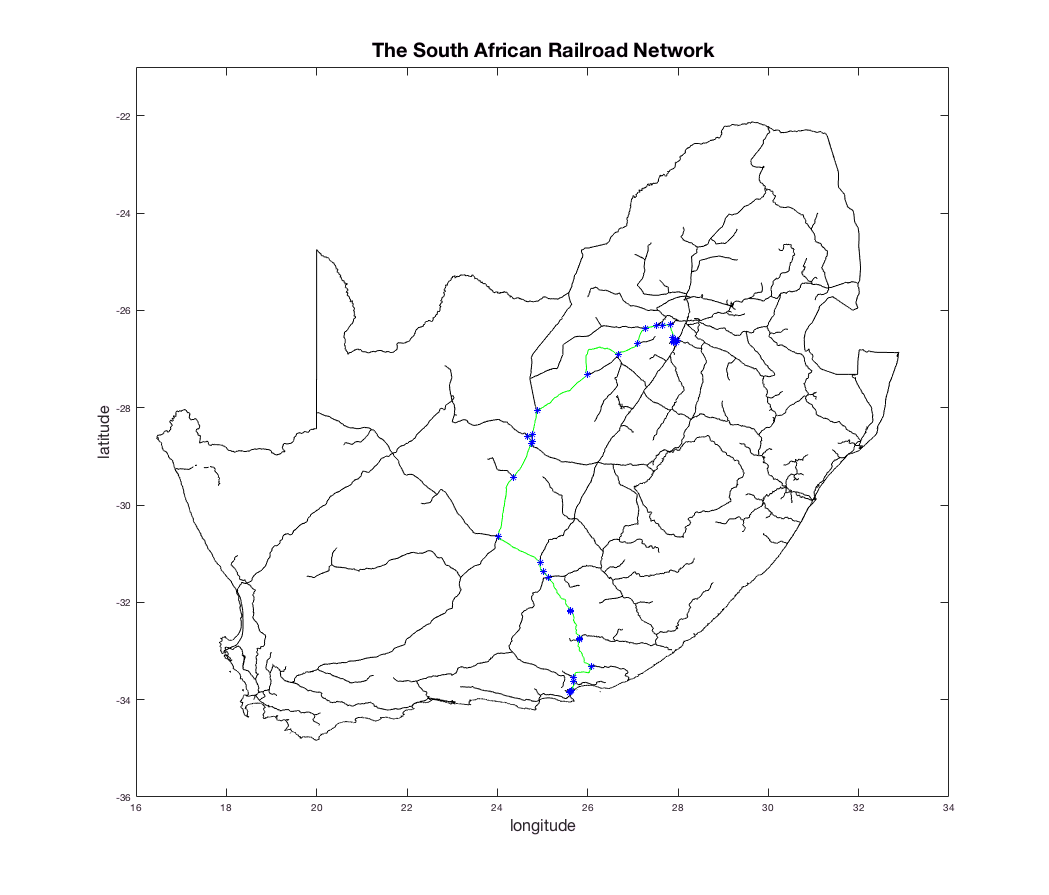

clf
initial = 33;
parent = P(initial);
lat_initial = stations(initial,1);
lon_initial = stations(initial,2);
lat_parent = stations(parent,1);
lon_parent = stations(parent,2);

for i = 1:497
    plot(s(i).Lon, s(i).Lat, 'k')
    hold on
end
hold on
plot(s_country.Lon, s_country.Lat, 'k')
while ~isnan(parent)
    for i = 1:497
        if ([s(i).Lat(1), s(i).Lon(1)] == [lat_initial,lon_initial])
            %if startpoint of current connection is location of current station
            if ([s(i).Lat(end-1), s(i).Lon(end-1)] == [lat_parent,lon_parent])
                plot(s(i).Lon, s(i).Lat, 'g')
                hold on
            end
        end
         if ([s(i).Lat(end-1), s(i).Lon(end-1)] == [lat_initial,lon_initial])
             %checking if the connection goes the other way round
            if ([s(i).Lat(1), s(i).Lon(1)] == [lat_parent,lon_parent])
                plot(s(i).Lon, s(i).Lat, 'g')
                hold on
            end
         end
    end
    plot(stations(initial,2), stations(initial,1),'b*')
    initial = parent;
    parent = P(initial,1);
    if isnan(parent)
        plot(stations(initial,2), stations(initial,1),'b*')
        break
    end
    lat_initial = stations(initial,1);
    lon_initial = stations(initial,2);
    lat_parent = stations(parent,1);
    lon_parent = stations(parent,2);
end
axis ([16 34 -36 -21])
title('The South African Railroad Network', 'FontSize', 20)
xlabel('longitude', 'FontSize', 16)
ylabel('latitude', 'FontSize', 16)